# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

# 9 Geochemical Problems

addpath ../codes
addpath ../codes/ternary
addpath ../data

clear all;

## 9.1 Introduction

Compositional data are any data that describe the constitutive makeup and their relative proportions of a sample.  There is no requirement that data be compositional sensu stricto to be considered compositional, only need to have similar characteristics of relative or proportional information about a sample.  Generally, the relative proportions are reported as fractions, percentages (mass, volume or molar) or concentration.  Common examples in geoscience include major and trace element concentrations, modal mineralogy, sand-clay-gravel fraction, quartz-feldspar-lithics.  Compositional data could be extended to a broader set of data including categorical data such as species counts when viewed as relative percentages of a total sample set rather than absolute population numbers.  In all these cases, the total of all constituents is a constant for all samples even if we do not record all the constituents.

Traditional statistical methods are not designed to handle compositional data, for which there are two issues, both related:

- the data are not entirely independent, there is one less degree of freedom than the number of components; and

- the data are bounded to a ***simplex***.

## 9.2 Aitchison Geometry/Simplex

### 9.2.1 Simplex

A ***simplex*** is simply the set of all possible constituent combinations bound to a constant.  We will use the notation, $\mathcal{S}^D$, to identify a simplex with $D$ components or dimensions needed to describe the sample.  A two-component simplex, $\mathcal{S}^2$, can be described as a line.  For example, olivine is a solid solution with two end-members (there are more, but we typically only examine two), forsterite and fayalite.  An olivine composition can vary anywhere between these two end-members from 0 to 100% of forsterite, with fayalite comprising the additional percentage up to 100%.  A three-component simplex, $\mathcal{S}^3$, can be graphically represented by a ternary diagram and a four-component simplex, $\mathcal{S}^4$, by a tetrahedron.  Simplexes of higher order are significantly more difficult to display graphically and even a 4-component can be difficult to interpret.

Suppose you are studying the carrying capacity of various points in a stream, which requires an analysis of particle size, measuring sand, clay and gravel fractions in a sediment.  As you look back over your notebook you realize that you forgot to record the sand fraction in a sample.  Do you know what the sand fraction was?  Of course you do, the total, must be 1, since they are the fraction of the total so the sand fraction is dependent upon the clay and gravel fractions.  In fact, you only need to record two out of the three components to describe the complete system, i.e., one less degree of freedom than the number of constituents.  As a result, the variables are not independent, and correlations may arise as a result that have nothing necessarily to do with a process.  For example, as igneous melts fractionate to very high silica values, the concentration of all elements begin to fall, typically above 80% wt.% SiO$_2$.  As SiO$_2$ approaches 100%, obviously everything else must decrease to zero.  Though each element may do so somewhat differently, most will be negatively related, if not correlated, to SiO$_2$.  This may not be explicitly related to the process of fractionation, making it difficult to determine the true relationships between the elements.

### 9.2.2 Closure

Compositional data can be difficult to analyze because of the large number of dimensions.  To simplify the dimensions, dimensions with similar properties may be combined, or only dimensions with specific characteristics or diagnostic properties.  By dropping other constituents, the sum of the remaining components may no longer be a constant, thus requiring normalization of the data before additional analyses may be conducted—a process is known as ***closure***.  (On a side note, like you, I don't understand why every field needs to have a different term to describe the same process, but closure is to statisticians what normalization is to geochemists.)  To ensure closure of a simplex, $\mathcal{S}^d$ with $d \leq D$ dimensions,


$$C(x_{i}) = \frac{k x_{i}}{\sum_{j \in d} x_{j}}$$


where $i \in d$ and $k$ is a defined constant where


$$k = \sum_{i \in d} C(x_{i})$$


The closure of compositional data to a simplex is referred to as placing the data onto an ***Aitchison geometry*** or ***Aitchison simplex***.

### 9.2.3 Mean of compositional data

It was alluded to previously in the course that arithmetic averages of compositional data are not appropriate to describe distributions.  Indeed, the geometric mean is the appropriate mean for a dimension in simplex space.

### 9.2.4 Operations on simplex data

There are three mathematical operations that are useful for simplex data.  A ***perturbation*** is computed by


$${\bf x} \oplus {\bf y} = \left[ \frac{x_1 y_1}{\sum_{i=1}^D x_i y_i}, \frac{x_2 y_2}{\sum_{i=1}^D x_i y_i}, \ldots, \frac{x_D y_D}{\sum_{i=1}^D x_i y_i} \right]$$


A ***powering*** is performed by


$$a \odot {\bf x} = \left[ \frac{x_1^a}{\sum_{i = 1}^D x_i^a}, \frac{x_2^a}{\sum_{i = 1}^D x_i^a}, \ldots, \frac{x_D^a}{\sum_{i = 1}^D x_i^a} \right]$$


An ***inner product*** is given by


$$\langle {\bf x},{\bf y} \rangle = \frac{1}{2 D} \sum_{i = 1}^D \sum_{j = 1}^D \log \frac{x_i}{y_i} \log \frac{y_i}{y_j}$$


## 9.3 Transformations

As mentioned in the introduction, our typical statistical methods are not generally defined for simplex spaces but are instead defined for real Euclidian space.  Therefore to use our standard statistical methods, we need a way to transform the Aitchison simplex into Euclidian space, i.e., $\mathcal{S}^D \to \mathbb{R}^d$.  These transformations are isomorphic, which means they can be inversely transformed.  Hence, it is possible to perform operations in the isomorphic space and inverse transform back to the Aitchison simplex.

### 9.3.1 Additive log-ratio (alr)

The simplest of the transforms converts the Aitchison simplex to Euclidian space by dividing the vector space by one of the dimensions of $x$ to create a ratio, which will serve to unbound $x$ on the right and taking the log of the ratio to achieve an unbounded transform on the left and right, i.e., $\mathcal{S}^D \to \mathbb{R}^{D-1}$, by 


$$\text{alr}({\bf x}) = \left( \log \frac{x_1}{x_D}, \ldots, \log \frac{x_{D-1}}{x_D} \right)$$


The alr transform also has the added advantage that it removes the redundant dimension in the data.  However, the alr transformation has some issues and is not used in practice.  The main issue is that because the ratio is reference to $x_D$, which changes for every sample, distance is not preserved.

### 9.3.2 Centered log-ratio (clr)

The clr is the most common log-ratio transformation that is used.  It is similar to the alr, but uses the geometric mean of the sample components, $g({\bf x})$, to compute the ratio rather than values for one of the dimensions of $x$.  The clr transformation,


$$\text{clr}({\bf x}) = \left( \log \frac{x_1}{g({\bf x})}, \ldots, \log \frac{x_D}{g({\bf x})} \right)$$


is unbounded but does not removed the redundant dimension; thus, $\mathcal{S}^D \to \mathbb{R}^D$.  Besides the retention of a redundant dimension, clr results in singular covariance matrices.  As a result the best choice is the isometric log-ratio transform (ilr) given below.  Distance is preserved under the clr transformation.

### 9.3.3 Isometric log-ratio (ilr)

The ilr transform uses a set of orthonormal basis vectors, which produces a transformation $\mathcal{S}^D \to \mathbb{R}^{D-1}$, removing the redundant dimension.  There are several methods that have been used to develop the orthonormal basis including Gram-Schmidt normalization and singular-value decomposition of the clr transformed data, and basis vectors determined from a bifurcating tree.  Regardless of the method to produce an orthonormal basis, the ilr transformation is completed by,


$$\text{ilr}({\bf x}) = \left( \langle {\bf x},{\bf e}_1 \rangle , \ldots, \langle {\bf x},{\bf e}_{D-1} \rangle \right)$$


Distance is preserved under the clr transformation.

% let's look at how each of these transformations affects a pca result
data = readtable('plutonic_geochem.xlsx');


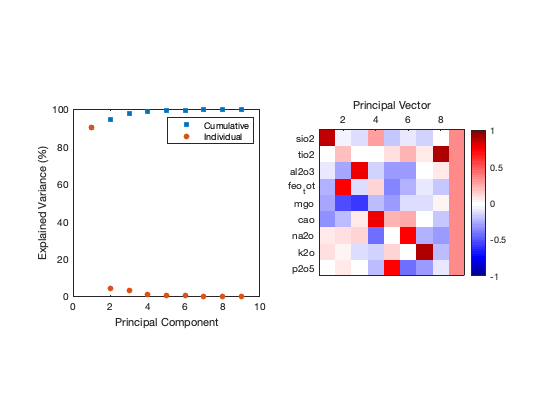

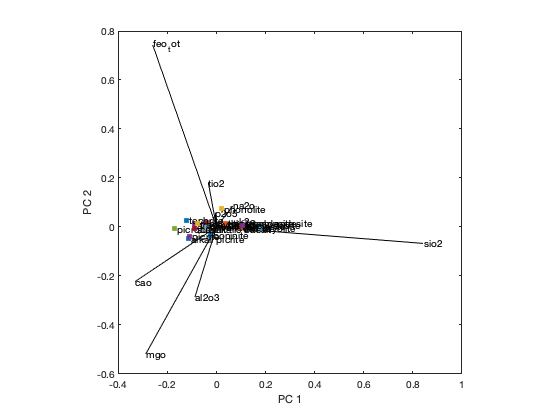

% from the normalized oxide data
db_pca(data);

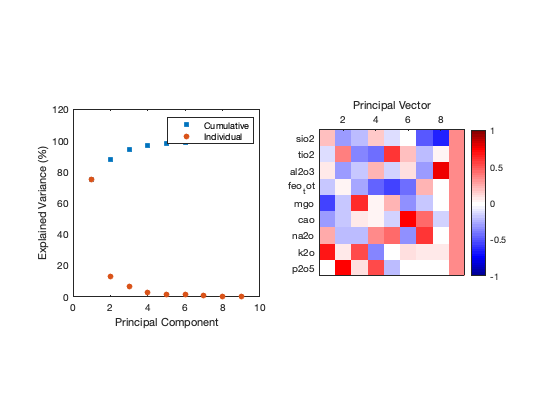

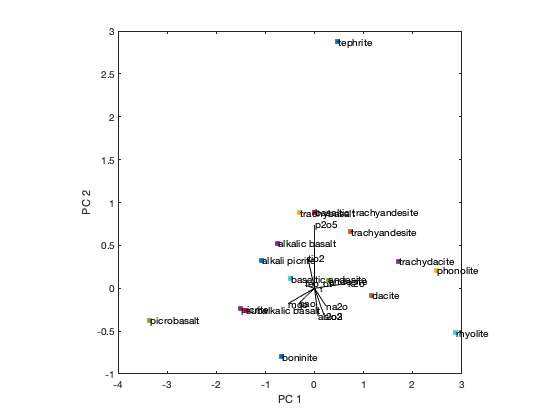

% using clr transformed data
db_pca(data,'clr');

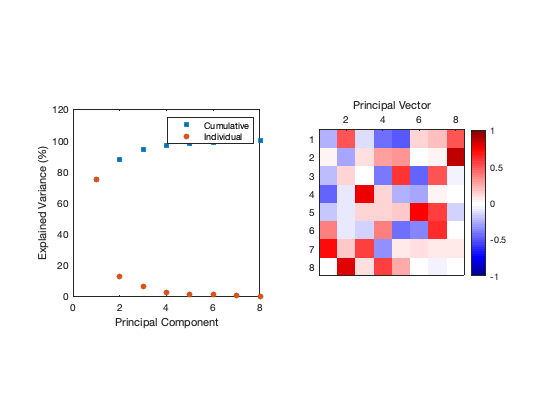

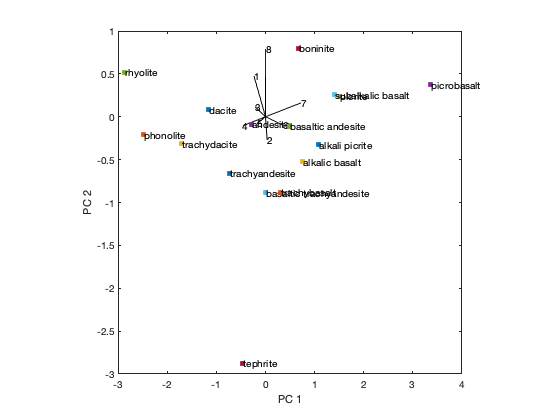

% using ilr transformed data
db_pca(data,'ilr');

## 9.4 Proportionality

As shown in Section 9.1, correlations are invalid on compositional data.  In response, several methods have been developed to explore the relationship between dimensions, referred to as ***proportionality metrics***. There are three metrics for proportionality, each performed on log-ratio transformed data:


$$\phi({\bf x_i} ,{\bf x_j}) = \frac{\text{Var}({\bf x_i} - {\bf x_j})}{\text{Var}({\bf x_i})}$$



$$\rho({\bf x_i} ,{\bf x_j}) = 1- \frac{\text{Var}({\bf x_i} - {\bf x_j})}{\text{Var}({\bf x_i}) + \text{Var}({\bf x_j})}$$



$$\phi_s({\bf x_i} ,{\bf x_j}) = \frac{\text{Var}({\bf x_i} - {\bf x_j})}{\text{Var}({\bf x_i} + {\bf x_j})}$$


Proportionality yields the same result in relative and absolute space whereas correlations may not, thus making proportionality a more reliable metric.

## 9.5 Ternary systems

Ternary diagrams are a favorite scheme of geochemists because they offer a much richer source of information on the chemical evolution of a system, potentially highlighting processes that are not discernible from a simple bivariate plot alone.  A ternary plot displays a minimum of three dimensions defined by an axis that extends from the vertex of an equilateral triangle bisecting the opposing edge.  Values along an edge represent the solid solution between the two components that terminate the edge.  The fraction of the system defined by the component labeled at the vertex varies from 1 (or 100%) at the vertex to 0 on the opposing edge.  The axes for the three components meet at the centroid of the ternary plot (1/3, 1/3, 1/3).  Of course like all plots it is generally easier to illustrate them than simply describe them.  Matlab doesn't have a native toolbox for producing ternary plots so I wrote a toolbox to make them.  You will find several different plotting functions that behave similar to MATLAB's standard plot functions including plot, scatter plot, and surface plot.  One nice feature that I have implemented in these plotting fucntions is the ability to extract data from the global geochemical dataset based on the vertex labels (parsea.m), which means that it parses a field like 'Na2O + K2O' by finding the relevant columns in the data table and adding them. The function also handles '-', '*', '/' and correctly interprets parentheses.

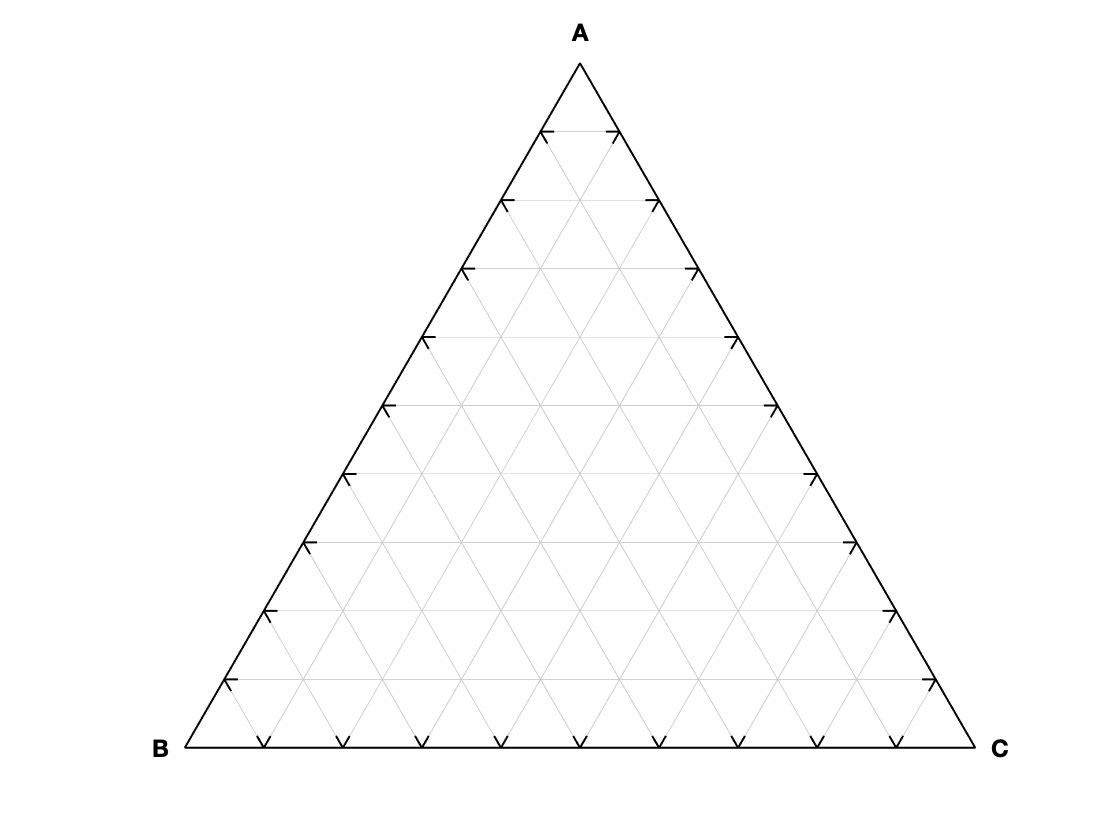

% create an empty ternary plot and add a grid, labels and tickmarks.
figure;
ternary;
ternlabel('A','B','C');

% Make a ternary diagram with data.
%data = readtable('plutonic_geochem.xlsx');

% Make a ternary diagram 
vertices = {'K2O','CaO','Na2O'};

% parse vertices, extracting the appropriate data
for i = 1:3
    A(:,i) = parsea(data,vertices{i},0);
end

% the data on a ternary diagram must be normalized to 1
T = sum(A,2);

% remove nan and negative data before normalizing
ind = ~isnan(T) & T > 0;
A = A(ind,:)./repmat(T(ind),1,3);

%figure;
ternsurf(A(:,1),A(:,2),A(:,3),data.sio2(ind),0.05);

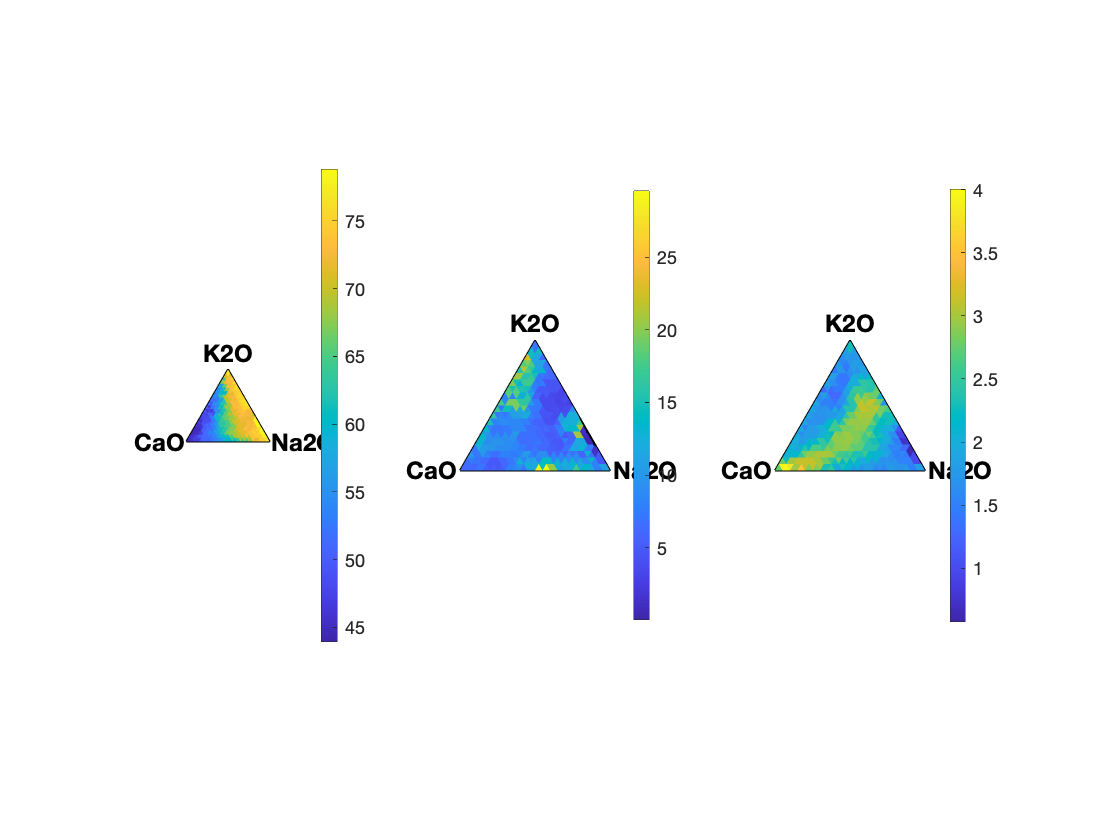

for i = 1:3
    subplot(1,3,i); hold on;
    ternlabel(vertices{1},vertices{2},vertices{3});
end

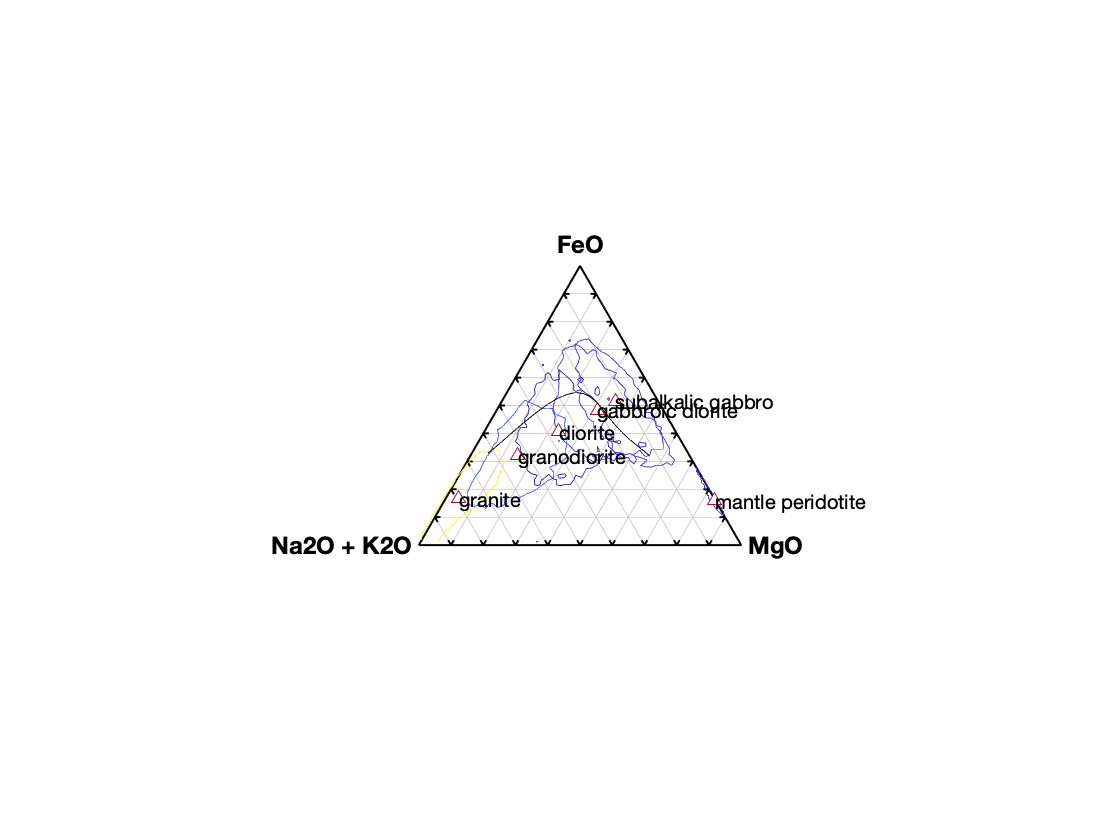


clear A

% Make a ternary diagram showing the progression of rock types with
% chemistry.  In this case, we examine the fractionation trend from mantle
% to granite on a calc-alkaline tholeiitic discrimination plot.  In the
% case below, I plot a single contour that encompasses 90% of the
% compositions of a single rock type.
rt = {'granite','granodiorite','diorite','gabbroic diorite', ...
    'subalkalic gabbro','mantle peridotite'};

vertices = {'FeO','Na2O + K2O','MgO'};

% parse vertices
% this line parses the math to create the appropriate data matrix for
% plotting, one column per vertex and recalculates to mole fraction (second
% argument 1, if necessary.
for i = 1:3
    A(:,i) = parsea(data,vertices{i},0);
end

% the data on a ternary diagram must be normalized to 1
T = sum(A,2);

% remove nan and negative data before normalizing
ind = ~isnan(T) & T > 0;
A = A(ind,:)./repmat(T(ind),1,3);

% extract rock types from data
rock_type = data.rock_type(ind);

figure;
% create ternary axes
ternary(vertices{1},vertices{2},vertices{3});

% plot a 90% contour for each rock type
c = 1;
for i = 1:length(rt)
    % find the rock type
    ind = strcmp(rt{i},rock_type);
    if sum(ind) == 0
        continue;
    end
    
    % contour only works in Cartesian (x,y) space, so change from ternary units to
    % Cartesian
    [x,y] = tern2xy(A(ind,1),A(ind,2),A(ind,3));
    % compute number of data in pixelated space
    [N,C] = hist3([x,y],[50 50]);
    hold on;
        
    n = N(N~=0);
    n = sort(n(:));
    
    % find values above the 10% cumulative level
    n10per = 0.1*sum(n(:));         % 10 percent of data
    itmp = sum(cumsum(n) < n10per); % index of 10 percent
    level = n(itmp);                % contour level encompassing 90% of the data

    % produce 90% contour
    contour(C{1},C{2},N',[level level],'-');
    
    %compute median value for rock type
    Am(c,:) = median(A(ind,:),1);
    
    tind(c) = i;
    c = c + 1;
end

hold on;
% plot median value
t = ternplot(Am(:,1),Am(:,2),Am(:,3),'^');
set(t,'MarkerFaceColor',[1 1 1]);

% label median values
[x,y] = tern2xy(Am(:,1),Am(:,2),Am(:,3));
for i = 1:length(x)
    text(x(i),y(i),rt{tind(i)});
end

% plot the calc-alkaline tholeiitic line
ca_thol_line;

## 9.6 Spider Diagrams

A spider diagram in geochemistry refers to a normalized plot of elements, generally ordered in decreasing compatibility in the reference system.  The elements are normalized with respect to a reference material, often chondritic meteorites, primitive mantle, or normal mid-ocean ridge basalts.  The purpose of normalizing is to remove a curious pattern that arises with abundance of adjacent elements (ordered by atomic number) forming a sawtooth pattern.  The pattern of elements that results from such an analysis can be used to identify processes such as fractionation, mixing, etc.  The use of spider diagrams is not necessarily a reduction of dimensions, but it allows one to highlight differences in the collective behavior of the dimensions between samples or groups of samples.

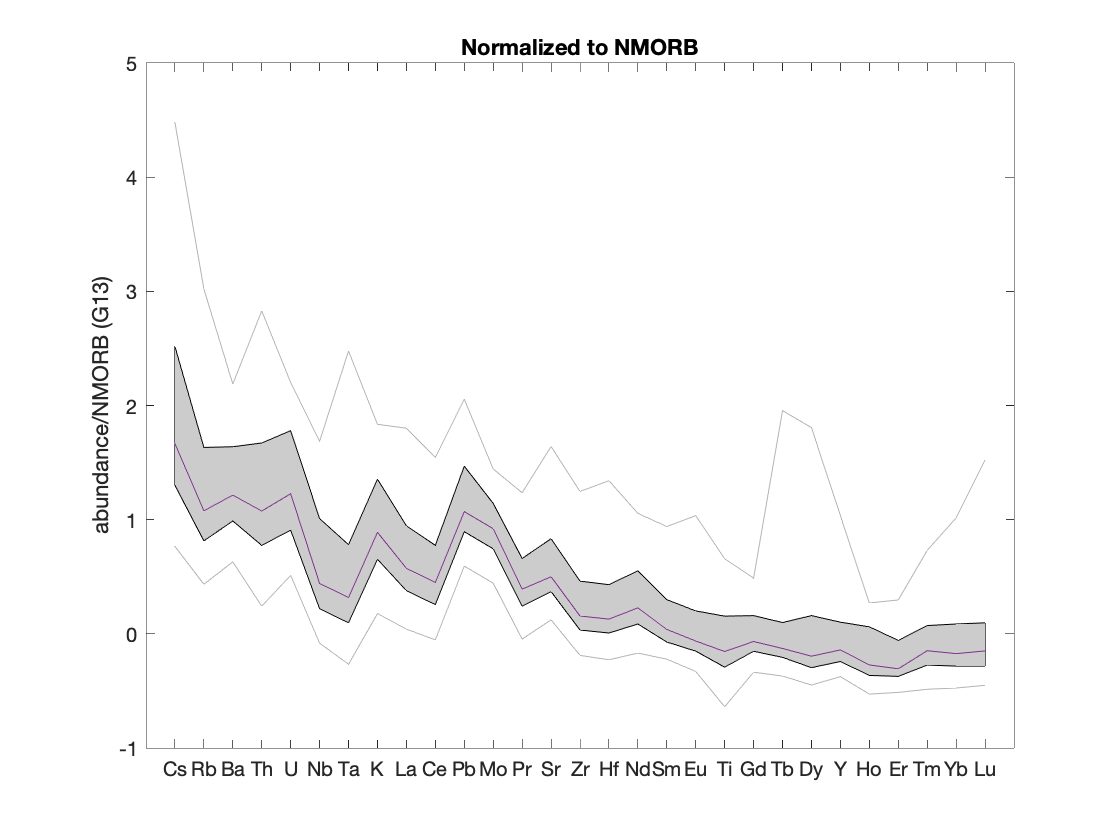

clear all;
data = readtable('cascades.xlsx');

% elements to display in spider diagram
ellist = {'Cs', 'Rb', 'Ba', 'Th', 'U', 'Nb', 'Ta', ...
    'K', 'La', 'Ce', 'Pb', 'Mo', 'Pr', 'Sr', ...
    'Zr', 'Hf', 'Nd', 'Sm', 'Eu', 'Ti', ...
    'Gd', 'Tb', 'Dy', 'Y', 'Ho', 'Er', 'Tm', 'Yb', 'Lu'};

% normalize to NMORB
normref = 'G13';

figure;
spider(data,normref,'Elements',ellist);